% Assume h is your measured impulse response and t is the time vector
% Make sure the Signal Processing Toolbox is available for findpeaks

% Find peaks in the impulse response
minPeakDist = 0.01; % Adjust this minimum peak distance as needed
[peakValues, peakLocs] = findpeaks(packedImpulse, t_conv);

if length(peakValues) >= 2
    % Compute logarithmic decrement from the first two peaks
    delta = log(peakValues(1)/peakValues(2));
    
    % Estimate damping ratio
    zeta = delta / sqrt(4*pi^2 + delta^2);
    
    % Compute damped natural frequency from the time difference between the first two peaks
    T_d = peakLocs(2) - peakLocs(1);
    omega_d = 2*pi/T_d;
    
    % Compute undamped natural frequency
    omega_n = omega_d / sqrt(1 - zeta^2);
    
    fprintf('Damping ratio (zeta): %f\n', zeta);
    fprintf('Damped natural frequency (omega_d): %f rad/s\n', omega_d);
    fprintf('Undamped natural frequency (omega_n): %f rad/s\n', omega_n);
else
    fprintf('Not enough peaks detected for reliable parameter estimation.\n');
end

Damping ratio (zeta): -0.166397


Damped natural frequency (omega_d): 1963.495408 rad/s


Undamped natural frequency (omega_n): 1991.255679 rad/s


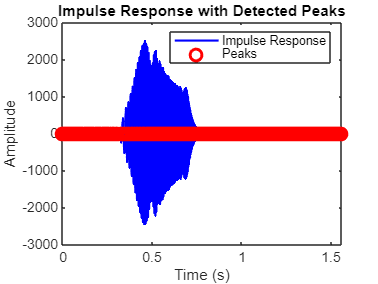


% Plot the impulse response with detected peaks
figure;
plot(t_conv, hrec, 'b-', 'LineWidth', 1.5);
hold on;
plot(peakLocs, peakValues, 'ro', 'MarkerSize', 8, 'LineWidth',2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response with Detected Peaks');
legend('Impulse Response', 'Peaks');

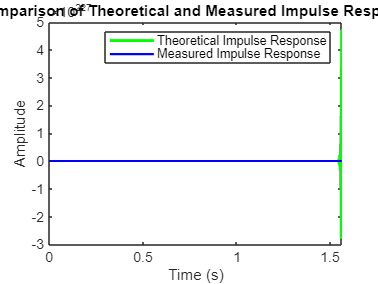




if length(peakValues) >= 2
    % Define the theoretical impulse response for an underdamped second order system
    % h(t) = (omega_n/sqrt(1-zeta^2)) * exp(-zeta*omega_n*t) * sin(omega_n*sqrt(1-zeta^2)*t) * u(t)
    t_theoretical = t_conv;  % Use the same time vector as the measured impulse response
    h_theoretical = (omega_n / sqrt(1 - zeta^2)) * exp(-zeta * omega_n * t_theoretical) ...
                    .* sin(omega_n * sqrt(1 - zeta^2) * t_theoretical);
    
    % Plot the theoretical impulse response and the measured one for comparison
    figure;
    plot(t_theoretical, h_theoretical, 'g-', 'LineWidth', 2);
    hold on;
    plot(t_conv, hrec, 'b-', 'LineWidth', 1.5);
    legend('Theoretical Impulse Response', 'Measured Impulse Response');
    title('Comparison of Theoretical and Measured Impulse Response');
    xlabel('Time (s)');
    ylabel('Amplitude');
else
    fprintf('Not enough peaks detected for reliable parameter estimation.\n');
end